# Week 7 Demo

## Revisiting ode45 and its timestepping

This week, we will be looking back at Forward Euler, but we will be reworking it to match the input structure of ode45.  To introduce some of the key ideas, let us first revisit problem 3 from last week.  Consider the second order IVP:

$y'' - (1-y^2)y' + y = 0$, $y(0)=2$, $y'(0) = 0$, $t\in[0,200]$.  

To solve this, you first converted it from a second-order ODE to a system of first-order ODEs.  If we let $y_1=y$ and $y_2 = y'$, you get the following system:

$\begin{cases} y_1' = y_2 \\ y_2' = -y_1 + (1-y_1^2)y_2 \end{cases}$ $y_1(0) = 2$, $y_2(0) = 0$.  

If we represent the system as an ode of a vector, $\mathbf{y} = [y_1, y_2]^T$, we get the following setup:

$\mathbf{y}' = \frac{d}{dt}\left[\matrix{y_1 \cr y_2}\right] = \left[\matrix{y_2 \cr -y_1 + (1-y_1^2)y_2}\right]$ , $\mathbf{y}_0 = \left[\matrix{2 \cr 0}\right]$.  

With this setup, we used ode45.  Last time, we used script functions as our input.  However, in some cases, it may be more efficient to create an anonymous function instead:

f = @(t,y) [y(2);-y(1)+(1-y(1)^2)*y(2)]; % assuming y is a 2d vector

Last time, I had you set tspan to a linspace from 0 to 200.  As you saw, you get a pretty jagged result:

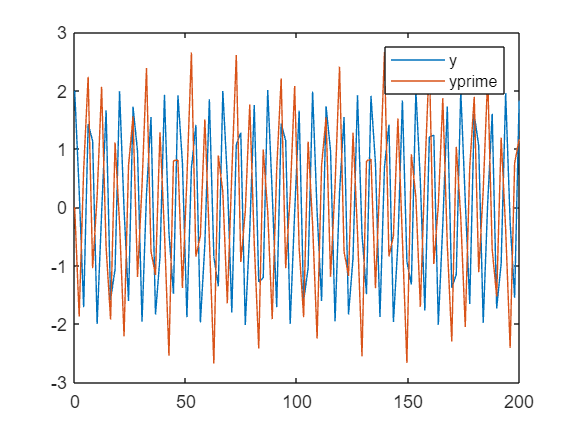

t0 = 0;
tf = 200;
tspan = linspace(t0,tf);
ic = [2,0];
[t,Y] = ode45(f, tspan,ic);

% plot y and y', and make a phase plane
figure 
y = Y(:,1); % first column of Y
yprime = Y(:,2); % second column of Y
plot(t,y)
hold on 
plot(t,yprime)
legend('y', 'yprime')

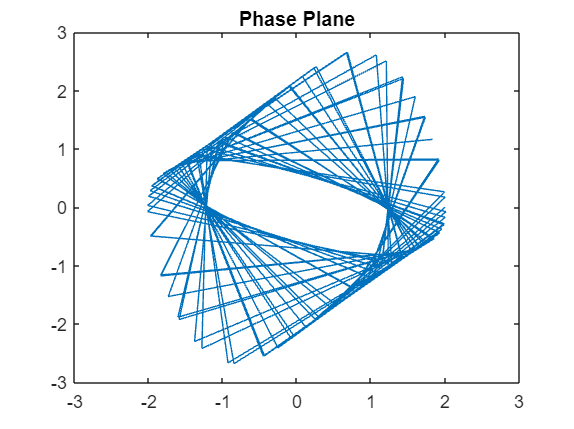


figure 
plot(y, yprime)
title('Phase Plane')

One way to address this is to increase the number of points:

tspan = linspace(t0,tf);
ic = [2,0];
[t,Y] = ode45(f, tspan,ic);

% plot y and y', and make a phase plane
figure 
y = Y(:,1); % first column of Y
yprime = Y(:,2); % second column of Y
plot(t,y)
hold on 
plot(t,yprime)
legend('y', 'yprime')


figure 
plot(y, yprime)
title('Phase Plane')

But what if we don't actually care about which points we are evaluating it at?  Well, if you prefer, you only need to give ode45 the endpoints:

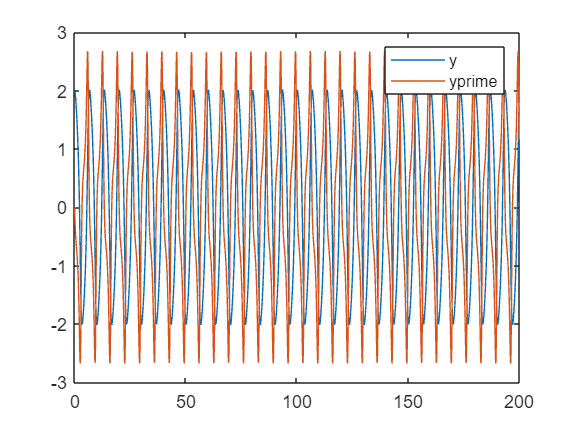

[t,Y] = ode45(f, [t0,tf],ic);

% plot y and y', and make a phase plane
figure 
y = Y(:,1); % first column of Y
yprime = Y(:,2); % second column of Y
plot(t,y)
hold on 
plot(t,yprime)
legend('y', 'yprime')

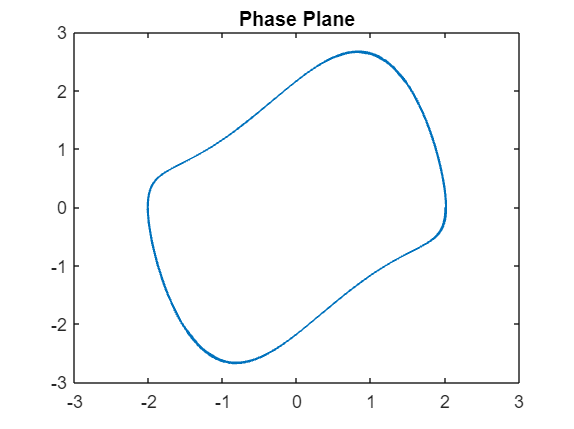


figure 
plot(y, yprime)
title('Phase Plane')

Today, you will rework your Forward Euler code to allow for this variability in how you input your tspan parameter.

## Creating functions to take inputs of variable dimension

Another thing you will be doing this week is creating a version of Forward Euler that can take *systems* of first-order ODEs (like ode45), not just single first order ODEs.  To see an example of such a function, let us consider a function which does the trival task of taking two variables, $\mathbf{x}$ and $\mathbf{y}$, and putting them into an array $[\mathbf{x},\mathbf{y}]$.  Here's the catch: we don't know the dimensions of $\mathbf{x}$ or $\mathbf{y}$, but we may assume that they have the same number of rows.  

Let's make a script function that does this (I will do this during lecture).  Lets call it create_array1.

Now, lets test it for a variety of cases for what $\mathbf{x}$ and $\mathbf{y}$ equal.

x = 1;
y = 2;
z = create_array1(x,y)

z =      1     2



y = [2 3 4]; % transpose y and get an error message
z = create_array1(x,y)

z =      1     2     3     4



x = ones(3,2);
y = zeros(3,4);
z = create_array1(x,y)

z =      1     1     0     0     0     0
     1     1     0     0     0     0
     1     1     0     0     0     0


What if we wanted to invert the dimensions of the resulting array?  We can create a similar code called create_array2 that implements the transpose operator (I will do this during lecture), and test it out:

z = create_array2(x,y)

z =      1     1     1
     1     1     1
     0     0     0
     0     0     0
     0     0     0
     0     0     0


## Updating entire rows of a matrix at a time:

So far, we have seen for-loops in the context of iterative sums as well as in the context of updating individual components of vectors.  I will demonstrate with a simple example how you can update entire rows of a matrix at a time with a similar technique:  Let us generate a placeholder matrix of dimension $N\times 3$, and then update each row such that each element in the $i$th row is equal to $i$:

N = 10;
M = zeros(N,3); % placeholder which we will upadate iteratively
for i = 1:N
    M(i, :) = i*ones(1,3);
end 
M

M =      1     1     1
     2     2     2
     3     3     3
     4     4     4
     5     5     5
     6     6     6
     7     7     7
     8     8     8
     9     9     9
    10    10    10


## A few remarks about this week's worksheet:

Problem 2 will challenge you to really think about a lot in terms of the dimensions of what's being created.  I strongly recommend you approach today's coding exercises with patience, as well as with a piece of paper/tablet to draw out what is going on.  Visualizing the dimensions and strucutes of your code is crucial for understanding, and it helps make the way you index things seem less abstract.  You will be using transpose operators and you will also be updating individual rows of an array at a time within a for-loop.  Remember the power of using a colon when you want to take/change an entire row/column.